%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 158356*0.946

W = 1.4980e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1693; %ft^2
AR = 8.23

AR = 8.2300

%AR2 = 5.23
%b2=100
TaperRatio = 0.4;
b = 118

b = 118

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
%e = 0.9;
%K = 1/(e*pi*AR)

%Fuselage Parameters
Df = 18; %ft
LNose = 16; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 4 %ft

DBase = 4

ABase = pi*DBase^2/4

ABase = 12.5664

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

%Induced Drag Factor

Ne = 4; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)

TaperFunc = 0.0053

K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)

K = 0.0531

e = 1/(K*AR*pi)

e = 0.7280


[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 20.4964

Cmac = 15.2259

Ymac = 25.2857

SweepMaxT = -1.7896

Cf = 18.6204

Sexp = 1.3409e+03

Re = 8.4781e+07

SweepMaxT = -1.7896

FF = 1.7035

Swet = 2.7556e+03

CDo = 0.0060


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0019


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0014


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.3934

CDoFuse = 0.0070


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

CDoNacelle = 0.0010


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0085


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0014


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 7.5415e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0280





CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.3570

LDMax = 0.7136

LDMax = 1.0694

LDMax = 1.4239

LDMax = 1.7769

LDMax = 2.1279

LDMax = 2.4764

LDMax = 2.8223

LDMax = 3.1650

LDMax = 3.5042

LDMax = 3.8396

LDMax = 4.1709

LDMax = 4.4977

LDMax = 4.8197

LDMax = 5.1367

LDMax = 5.4485

LDMax = 5.7546

LDMax = 6.0550

LDMax = 6.3494

LDMax = 6.6377

LDMax = 6.9195

LDMax = 7.1949

LDMax = 7.4636

LDMax = 7.7255

LDMax = 7.9805

LDMax = 8.2285

LDMax = 8.4695

LDMax = 8.7035

LDMax = 8.9302

LDMax = 9.1499

LDMax = 9.3623

LDMax = 9.5676

LDMax = 9.7658

LDMax = 9.9568

LDMax = 10.1408

LDMax = 10.3178

LDMax = 10.4878

LDMax = 10.6510

LDMax = 10.8073

LDMax = 10.9570

LDMax = 11.1001

LDMax = 11.2367

LDMax = 11.3669

LDMax = 11.4908

LDMax = 11.6087

LDMax = 11.7204

LDMax = 11.8264

LDMax = 11.9265

LDMax = 12.0211

LDMax = 12.1101

LDMax = 12.1939

LDMax = 12.2724

LDMax = 12.3459

LDMax = 12.4144

LDMax = 12.4782

LDMax = 12.5373

LDMax = 12.5920

LDMax = 12.6423

LDMax = 12.6883

LDMax = 12.7303

LDMax = 12.7683

LDMax = 12.8025

LDMax = 12.8330

LDMax = 12.8600

LDMax = 12.8835

LDMax = 12.9037

LDMax = 12.9207

LDMax = 12.9347

LDMax = 12.9457

LDMax = 12.9538

LDMax = 12.9592

LDMax = 12.9620

LDMax = 12.9623

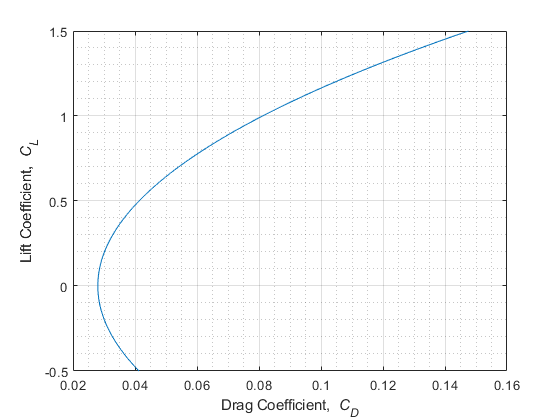


% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

plot (CD,CL)

xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
grid minor


LDMax

LDMax = 12.9623